# Experimental Methods HW #3 Dan Lawson

## Problem 1: Curve Fit

% Using Least-Squared method, find a and b values for the best fit and plot
% Data is of the form y = ax^b

clear
x_1 = [0.5, 2.0, 5.0, 10];
y_1 = [0.14, 2.51, 15.3, 63.71];
x_1_smooth = linspace(0, 10, 1000);

log_x = log(x_1);
log_y = log(y_1);
A = [length(x_1), sum(log_x); sum(log_x), sum(log_x.^2)];
f = [sum(log_y); sum(log_y.*log_x)];
A_inv = inv(A);
c = A_inv * f;
a = exp(c(1))

a = 0.5858

b = c(2)

b = 2.0387

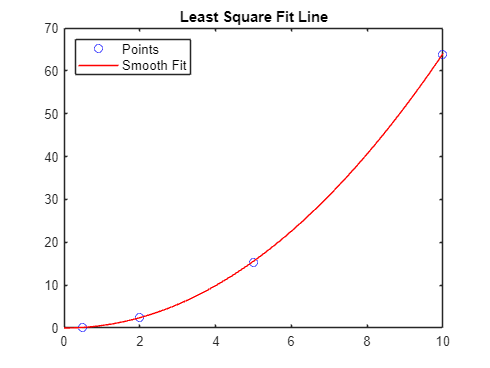


y_1_smooth = a * x_1_smooth.^b;

figure;
plot(x_1, y_1, 'bo', 'DisplayName', 'Points');
hold on;
plot(x_1_smooth, y_1_smooth, 'r-','DisplayName', 'Smooth Fit');
legend('FontSize', 10, "Location","northwest");
title('Least Square Fit Line')

## Problem 2: Weighted Curve Fit

% Data is in the form of y = a + b*sqrt(x)

clear
x_2 = [1,2,3,4,5,6,7,8,9,10];
y_2 = [2.2, 2.9, 2.8, 3, 3.1, 3.1, 3.2, 3.0, 2.9, 3];
sig_y_2 = [0.8, 0.3, 0.2, 0.2 ,0.2, 0.2, 0.2, 0.5, 0.5, 1.0];
w = 1./(sig_y_2.^2);
x_2_2 = x_2.^0.5;
conf = 0.9;
nu = length(x_2) - 1;

% Using the weighted least-sqaure method, compute a and b for the best fit

delta = sum(w) * sum(w .* x_2) - (sum(w .* x_2_2))^2;
A_2 = (sum(w .* x_2) * sum(w .* y_2) - sum(w .* x_2_2) * sum(w .* x_2_2 .* y_2)) / delta

A_2 = 2.4227

B_2 = (sum(w) * sum(w .* x_2_2 .* y_2) - sum(w .* x_2_2) * sum(w .* y_2)) / delta

B_2 = 0.2713


sig_a = sqrt(sum(w .* x_2) / delta);
err_abs_a = sig_a * tinv(conf, nu)

err_abs_a = 0.5906

sig_b = sqrt(sum(w) / delta);
err_abs_b = sig_b * tinv(conf, nu)

err_abs_b = 0.2653

x_2_smooth = linspace(1, 10, 1000);
y_2_smooth = A_2 + B_2 * x_2_smooth.^0.5;

% Using the unweighted least-square method, repeat step 1

A_2_uw = [length(x_2), sum(x_2_2); sum(x_2_2), sum(x_2)];
f_2 = [sum(y_2); sum(y_2 .* x_2_2)];
A_inv_2 = inv(A_2_uw);
c_2 = A_inv_2 * f_2;
a_2 = c_2(1)

a_2 = 2.3195

b_2 = c_2(2)

b_2 = 0.2672

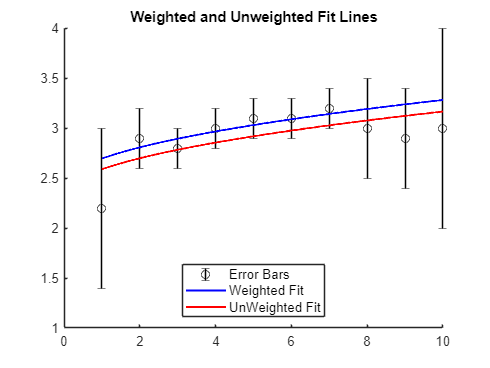

y_2_uw = a_2 + b_2 * x_2_smooth.^0.5;

% Plot the data with Y error bars on the best fit line

figure;
% plot(x_2, y_2, 'ko', 'DisplayName', 'Points');
hold on;
errorbar(x_2, y_2, sig_y_2, 'ok', 'DisplayName', 'Error Bars');
plot(x_2_smooth, y_2_smooth, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Weighted Fit');
plot(x_2_smooth, y_2_uw, 'r-', 'LineWidth', 1.5, 'DisplayName', 'UnWeighted Fit');
legend('FontSize', 10, 'Location','south');
title('Weighted and Unweighted Fit Lines');